# SEE data-driven NCC

## Read all .txt files in the folder

dinfo = dir('*.txt');
names_cell = {dinfo.name}';
names_Str = convertCharsToStrings(names_cell)

names_Str = 4×1 string array
    "1a_AuNpsNIE.txt"
    "1b_AuNpsBlank.txt"
    "2a_CatalaseNIE.txt"
    "2b_CatalaseBlank.txt"


## Import data by input the files' name

thisSignalAnalysis = SignalAnalysis(Filename)

Input -- **Filename** as a string, by defalut, consider there are other text string in the data file

Output -- **Sig.test_signal** Original signal vector in original unit

                **Sig.Test_time** Original time vector in original unit by default think it's in second 

                **Sig.Test_freq** test frequency depends on the test_time vector by default it's Hz

    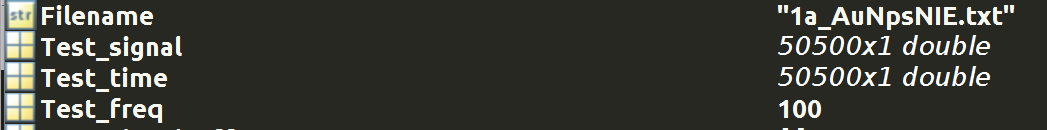

Sig1 = SignalAnalysis(names_Str(1));
Sig2 = SignalAnalysis(names_Str(3));
Back1 = SignalAnalysis(names_Str(2));
Back2 = SignalAnalysis(names_Str(4));

## Preprocess

[theSignalAnalysis] = Preprocess(theSignalAnalysis,OriginalUnit,Timeshift,Resample,ResamplePlot)

Input -- 

**OriginalUnit** a string of orgiginal data's unit e.g. 'pA', it will convert different current into pA in this toolbox 

**Timeshift** whether or not performing the time shift, will shift the test_time starts from 0 input string as e.g. 'y'

**Resample** whether or not to perform the resampling for uneven sampling, input string as e.g. 'y'

**ResamplePlot** whether or not to show the plot with and without resampling , input string as e.g. 'y'

Output -- 

**Sig.test_signal** converted unit signal vector, depending on chosen option becomes resampled signal 

**Sig.Test_time** updated time vector in original unit, depending on chosen option becomes shifted time from 0

**Sig.Test_freq **updatedtest frequency depends on the test_time vector

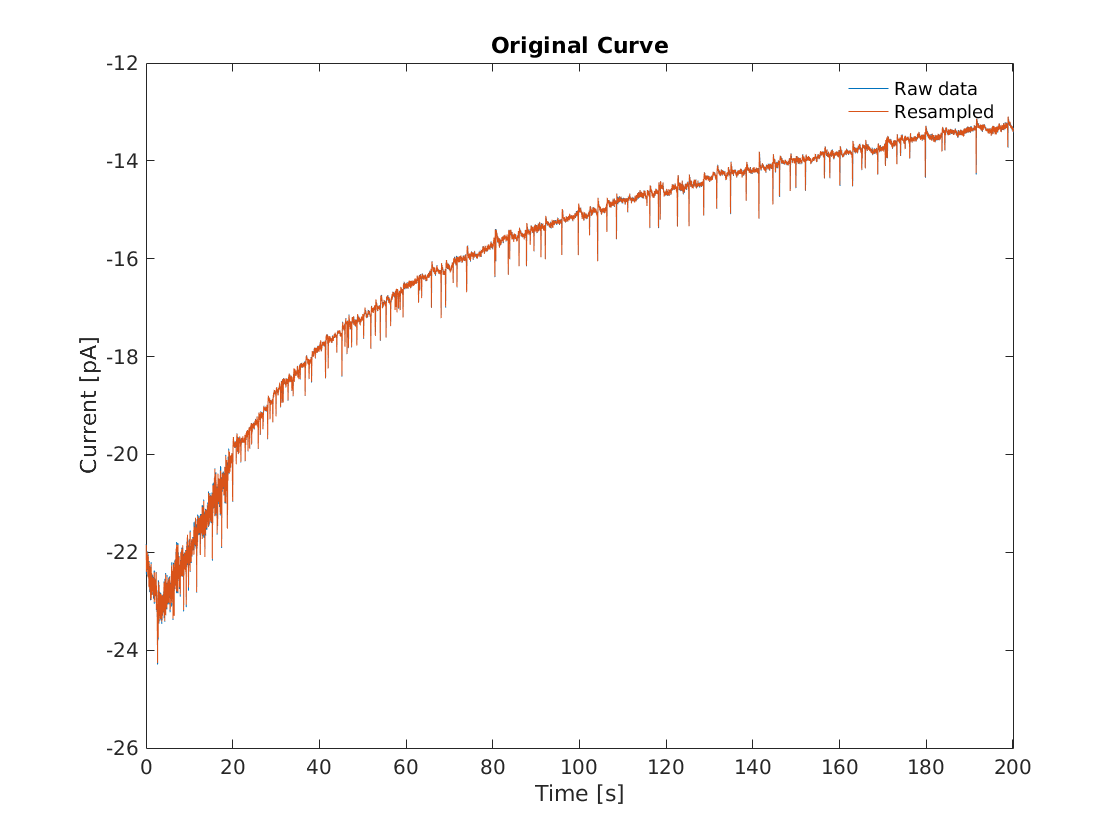

Sig1 = Sig1.Preprocess("A","Y","N","N");
Back1 = Back1.Preprocess("A","Y","N","N");
Sig2 = Sig2.Preprocess("PA","N","Y","Y");

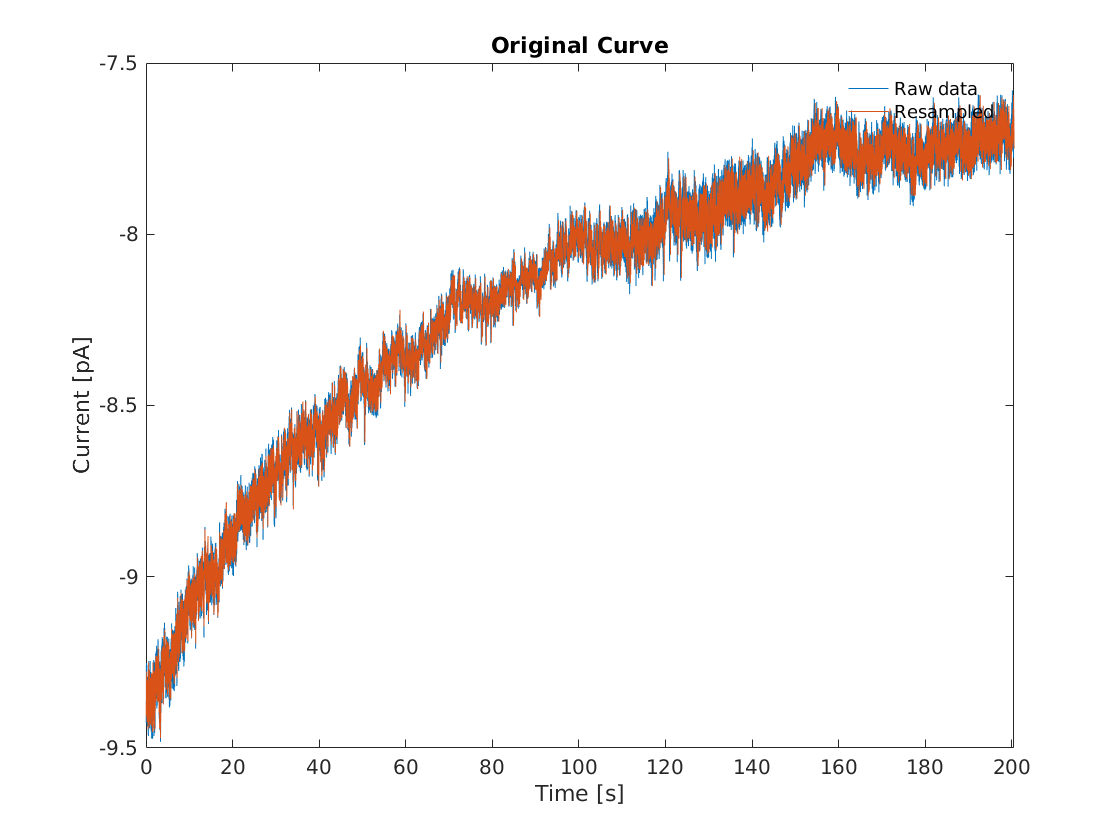

Back2 = Back2.Preprocess("PA","N","Y","Y");

## Denoise

Removing the undesired electrical noise

[theSignalAnalysis] = Denoise(theSignalAnalysis,CutoffFreq,FilterOrder,Plotstates)

Input --  

**CutoffFreq** the cut-off frequency to apply for FIR filter, the spike frequency can get from stft plot by leaving CutoffFreq empty, suggest running in .m since the in .mlx the plot won't show instantly e.g. 10

**FilterOrder **the order for the FIR filter also known as term number,  higher the order, shaper the filter at pass band, but higher the delay, we din't perform the zero-phase filtering in this toolbox e.g. 10, can be changed in the command window it will ask wether or not to change, if enter no or nothing it won't change 

**Plotstates** whether or not showing the plot for the denoised signal, e.g. 'Y'  

Output -- 

**Sig.test_signal** Denoised signal

**Sig.Test_time **After denoising the time vector may shift due to the convolution, the filter length of data get abandoned (normally less than 20)

Denoise can either leave frequency it will output the stft plot and set frequency by inputing in the command window

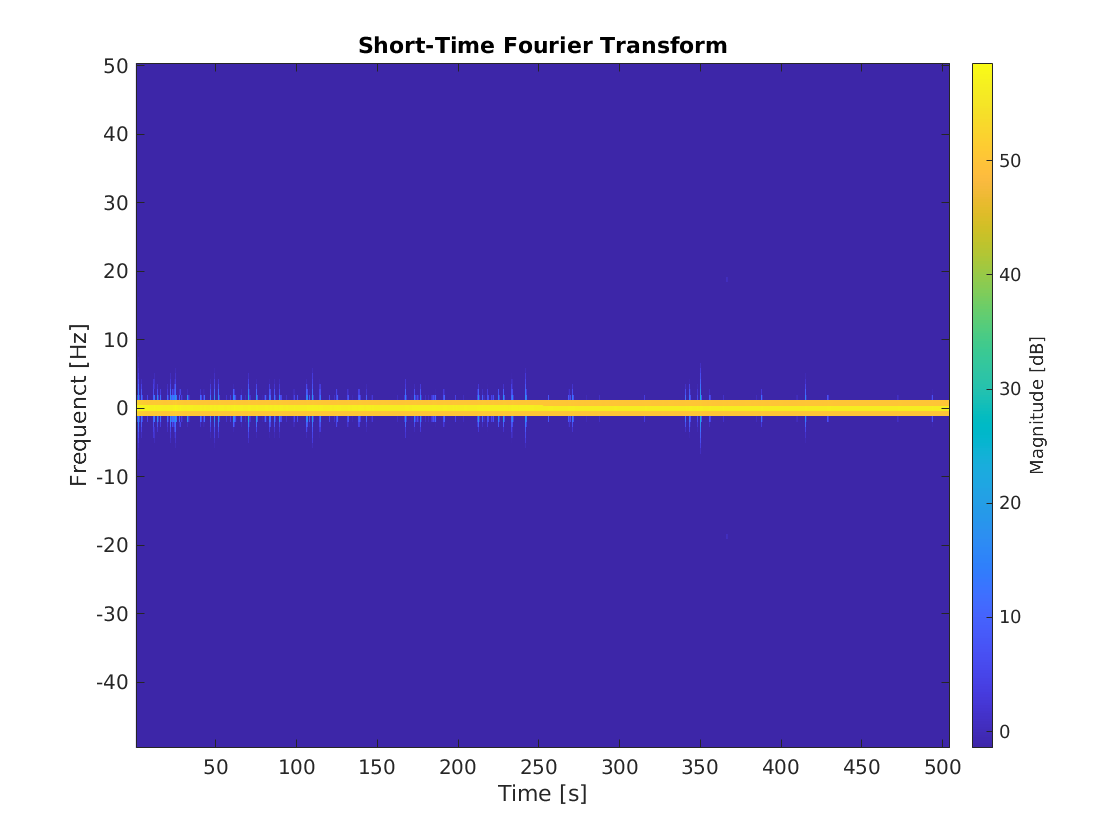

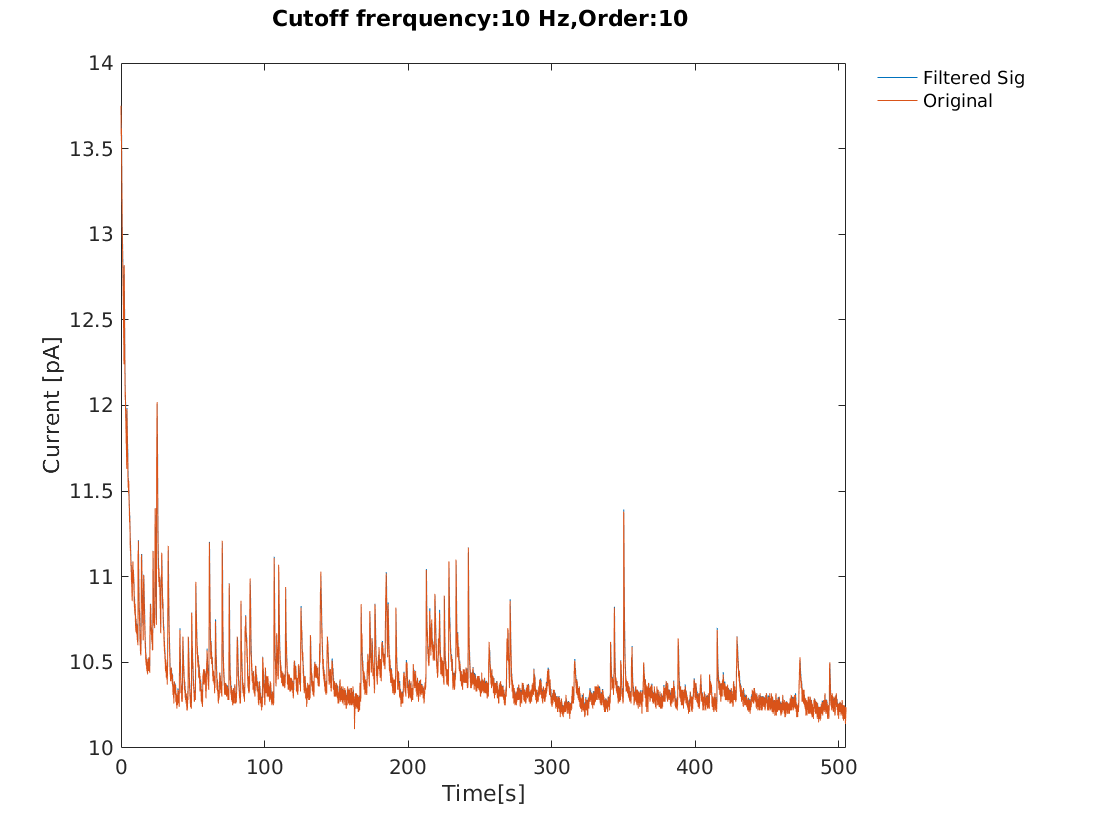

Sig1 = Sig1.Denoise([],10,"Y");

Or directly input the cut-off frequency

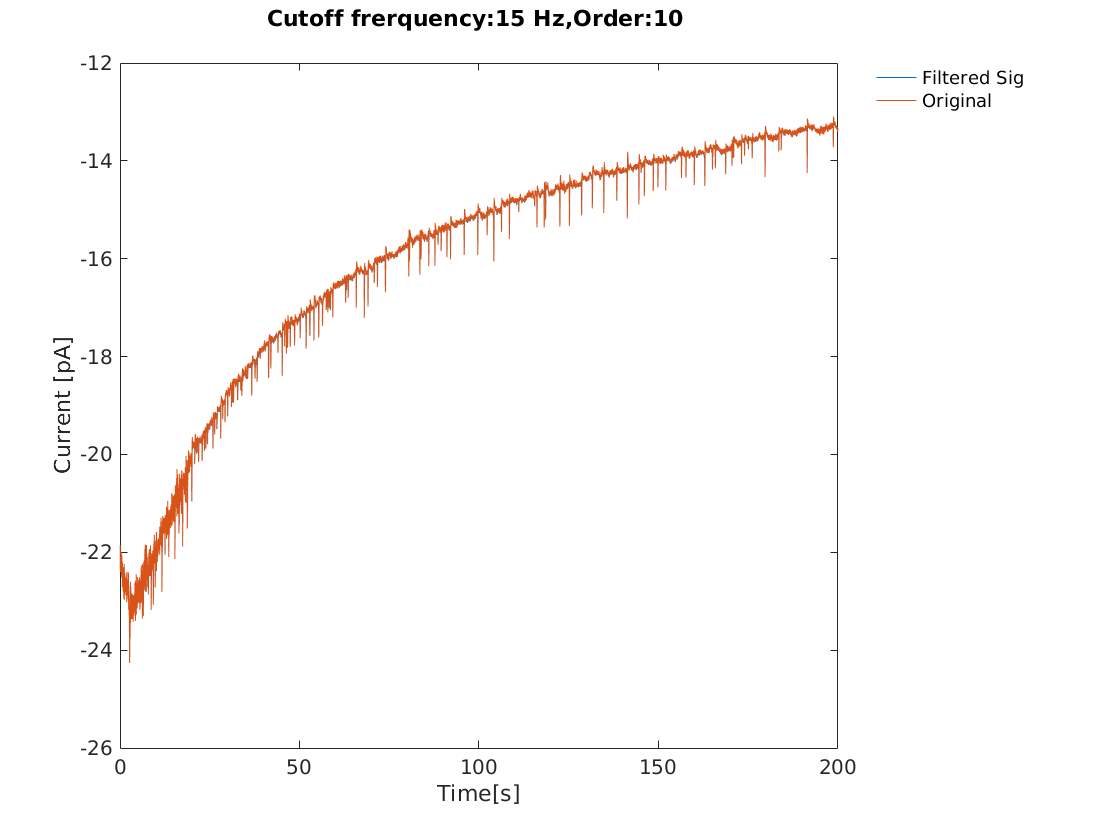

Sig2 = Sig2.Denoise(15,10,"Y");

## BackgroundSubtraction 

Correct baseline into 0 baseline

[theSignalAnalysis] = BgSub(theSignalAnalysis,WinSize,Plotstates)

Input -- 

**WinSize** Windows size, by default set as 1000, lower the value, and the curve fits better the NIE spikes(undesired).

**Plotstates** whether or not showing the plot for the background subtraction, Output a subplot the first is the test_signal with a fitted trend line. The second one is the offset signal

Output--

**Sig.test_signal_offset **Offset signal data vector

**Sig.test_signal_trendline **Fitted trendline 

#### Fitted trend line for AuNp Sig1

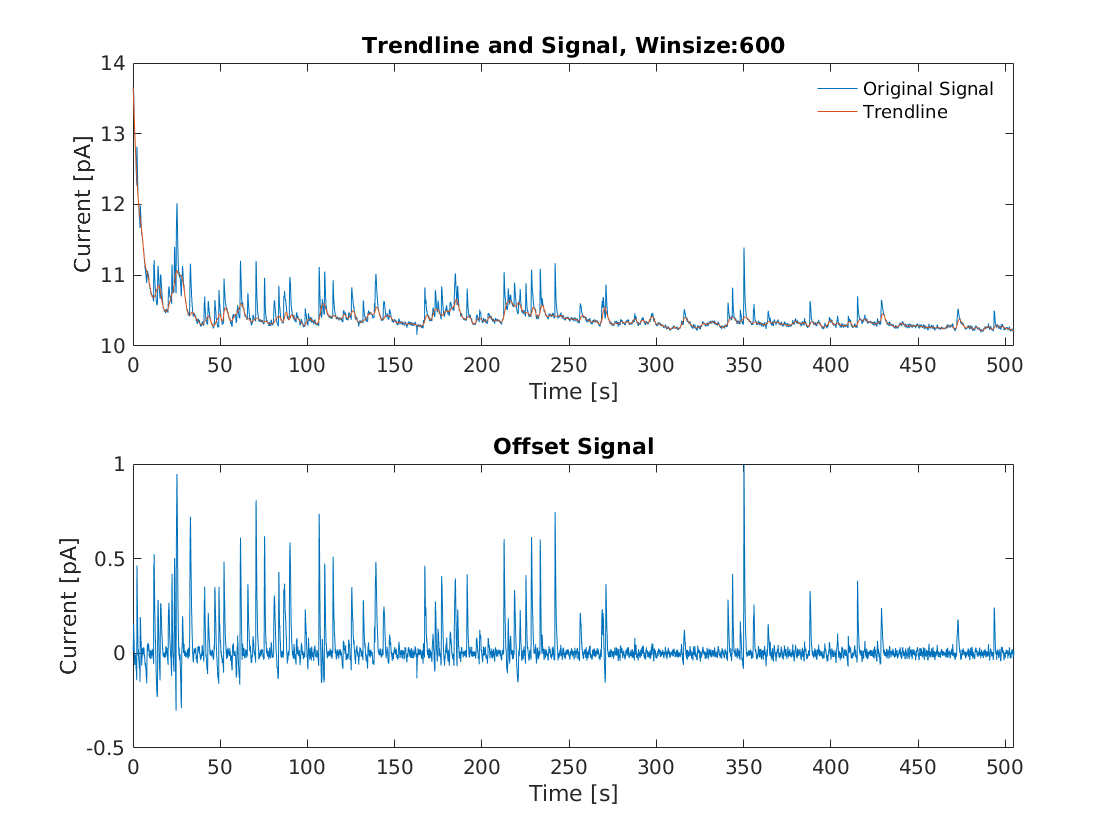

Winsize = 600;
Sig1 = Sig1.BgSub(Winsize,'y');

Back1 = Back1.BgSub(1000,'N');

#### Fitted trend line for Catalase Sig2

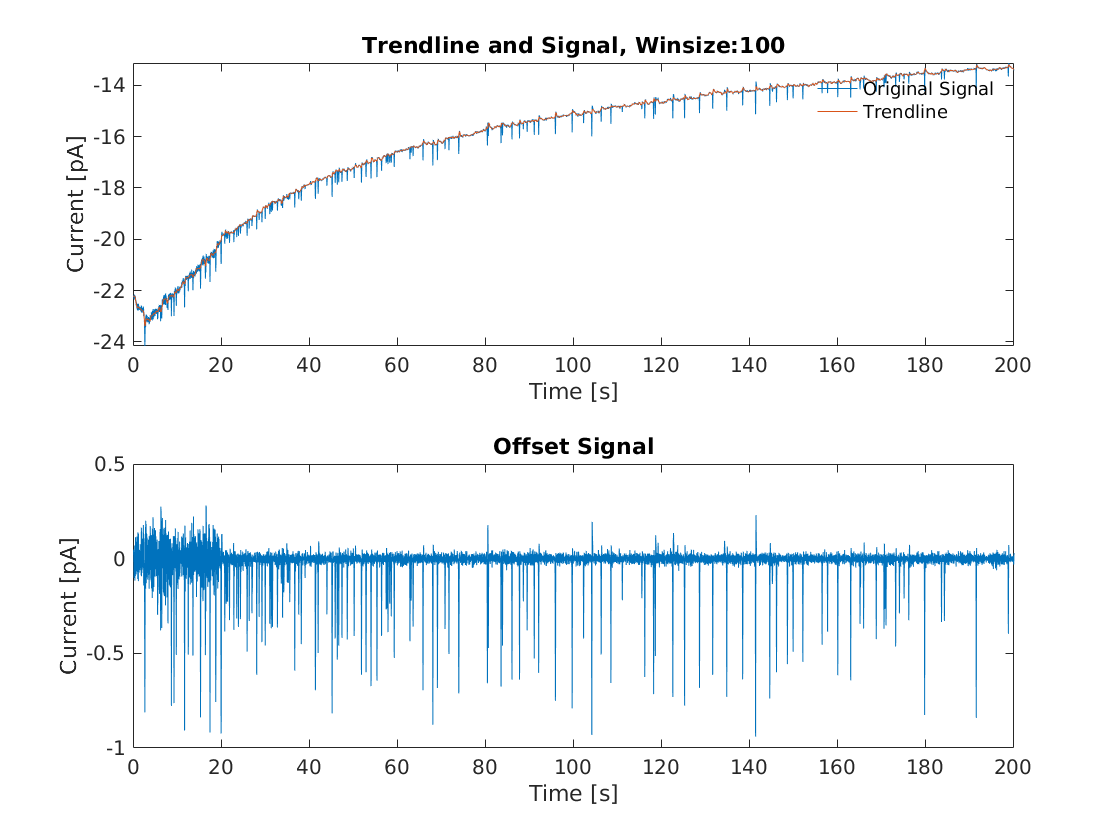

Winsize = 100;
Sig2 = Sig2.BgSub(Winsize,'y');

Back2 = Back2.BgSub(1000,'N');

## Sampling peaks by height threshold based on blank

 [theSignalAnalysis] = FlipFindPeak(theSignalAnalysis,BackgroundSigOffset,ReactionStates,Plotstates,PlotIndex)

Input --

**BackgroundSigOffset **Blank data vector of the corresponding experiments 

**ReactionStates **define the oxidative or reductive NIE spikes, as 'Oxi' or 'Red'

**Plotstates **Whether or not to show the plot e.g. 'Y'

**PlotIndex **to plot found interval on the offset or original signal "Original" or "Offset"

Output -- 

**Sig.Reactionstates **same as input ReactionStates

**Sig.BackGroundHeightThr** Height threshold calculated according to the Blank data

**Sig.FlipFindInte **Found interval by height threshold in data index, first column left point, second column right points. 

**Sig.PeaksFound** three colum vectors first colum as height, second the peak location in index, third the width unit as second.

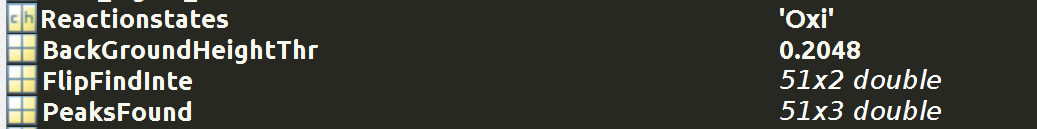

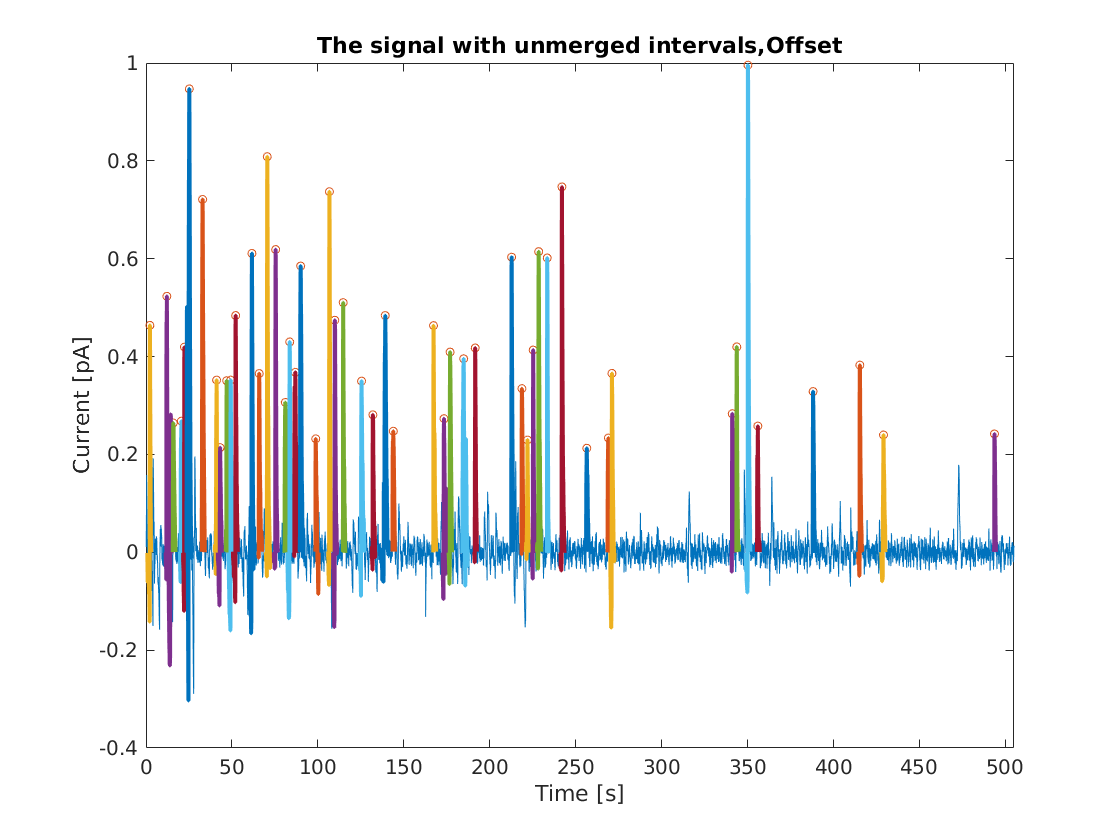

Sig1 = Sig1.FlipFindPeak(Back1.Test_signal_offset,'Oxi','Y',"Offset");

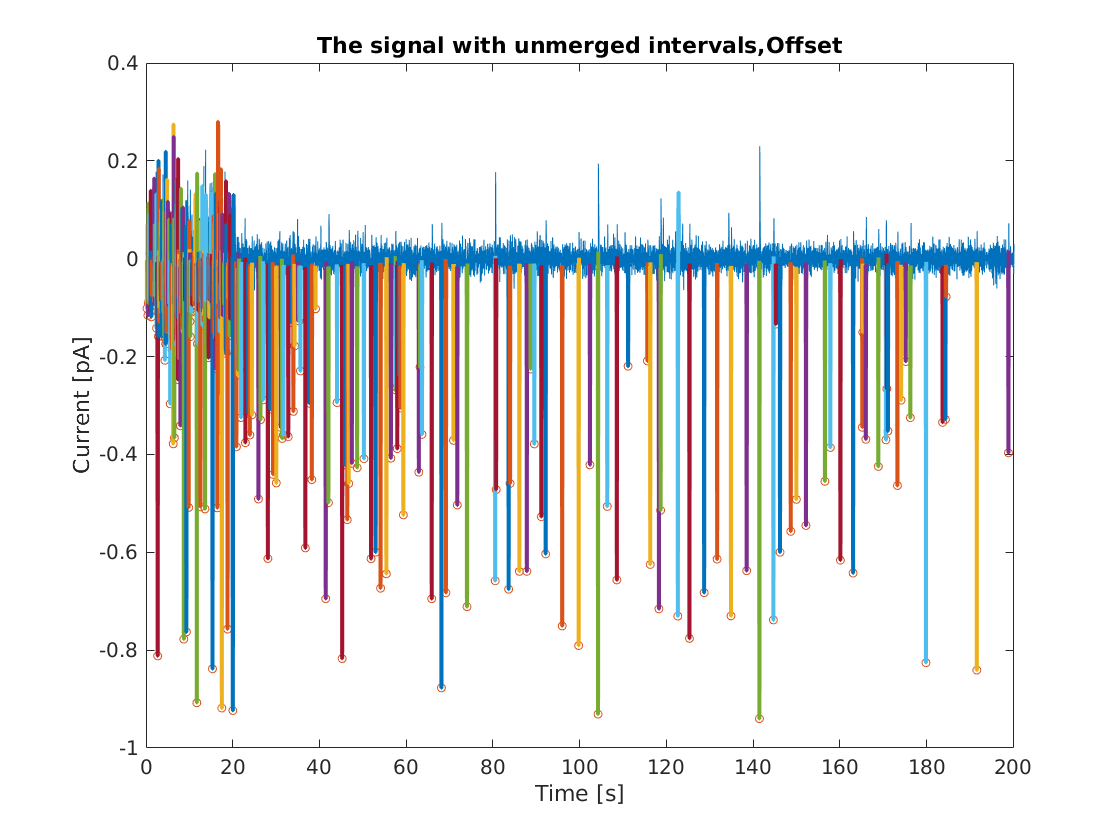

Sig2 = Sig2.FlipFindPeak(Back2.Test_signal_offset,'Red','Y',"Offset");

## TrainingSet generation

Generate the training sets for clustering NIE spikes and noisy spikes, and show the plot for selecting nuber of centroids.

[theSignalAnalysis] = GeRawTrainSet(theSignalAnalysis,NumPlot,SilPlot)

Input--

**NumPlot** Whether or not to show Elbow method plot to decide the cluster numbers

**SilPlot** Whether or no to show silhouette score plot to decide centroid number 

Output--

**Sig.RawTemClusterFeatures** A table of clustering features, order same as **Sig.FlipFindInte**

**Sig.RawTemClusterFeaturesNorm** Z-score normalized cluster features 

**Sig.RawTemFeaturesMu **Corresponding mean value for each feature

**Sig.RawTemFeaturesSigma **Corresponding standard deviation value for each feature

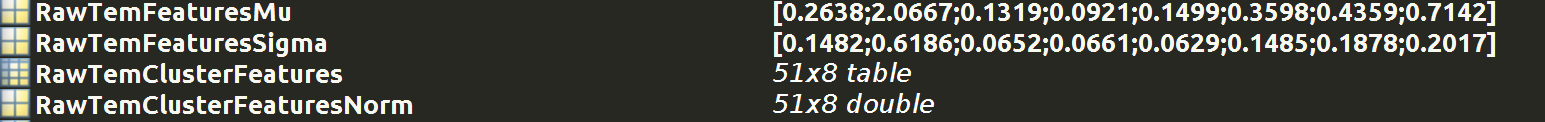

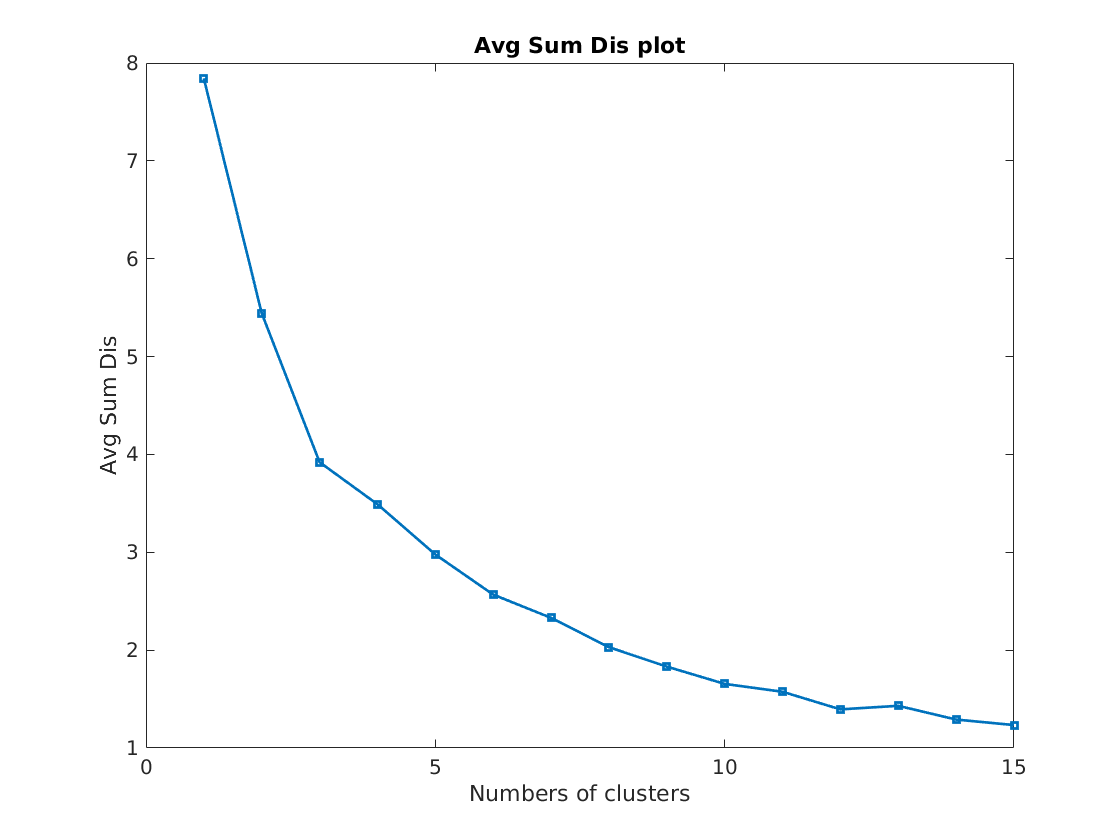

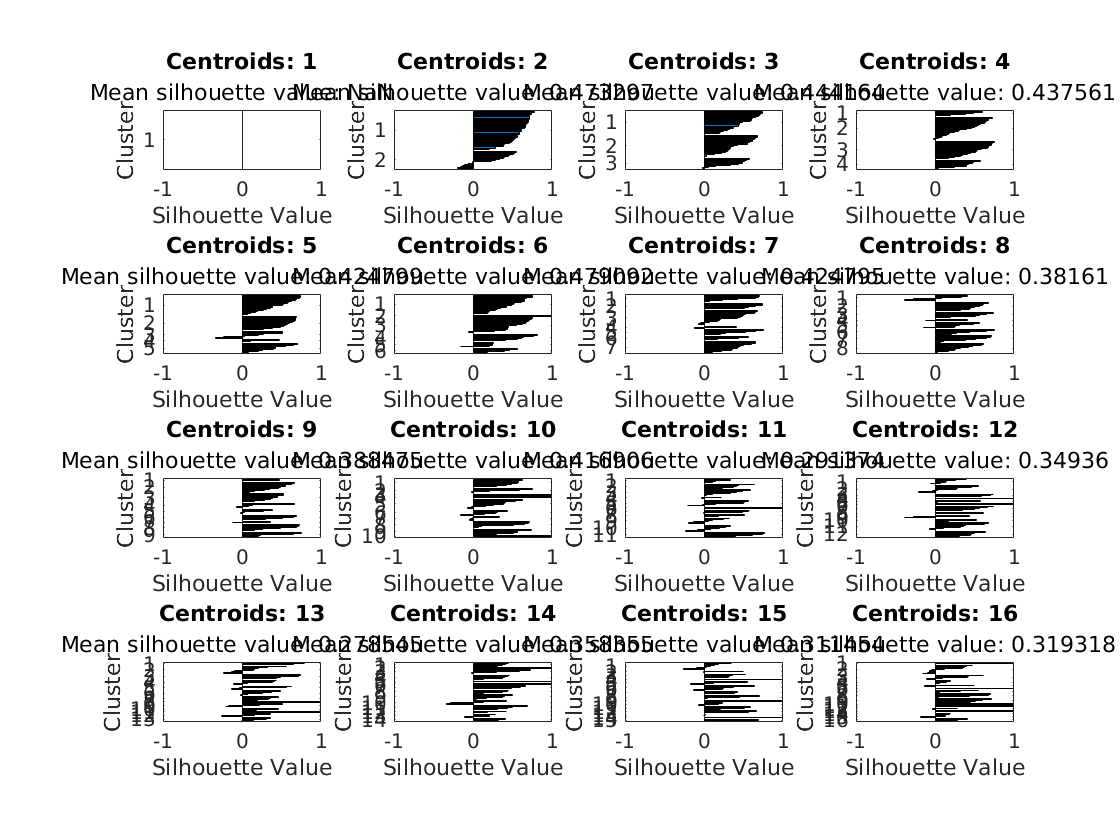

Sig1 = Sig1.GeRawTrainSet('Y','Y');

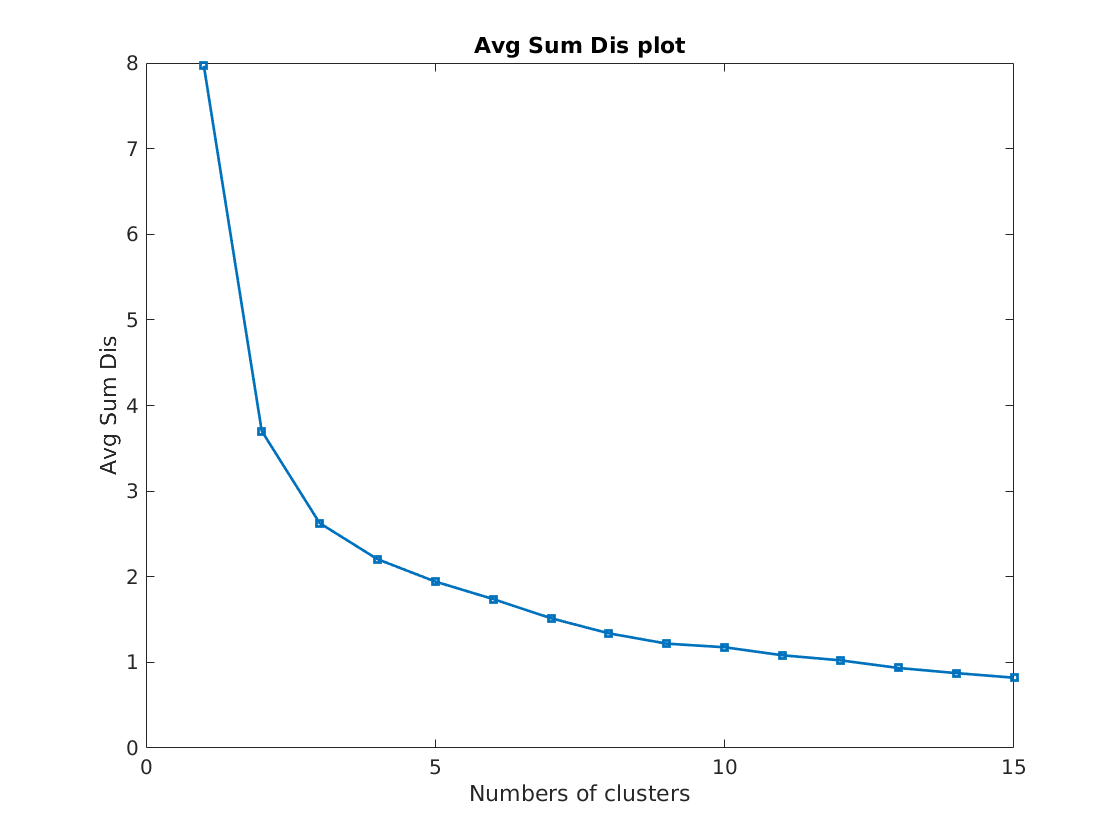

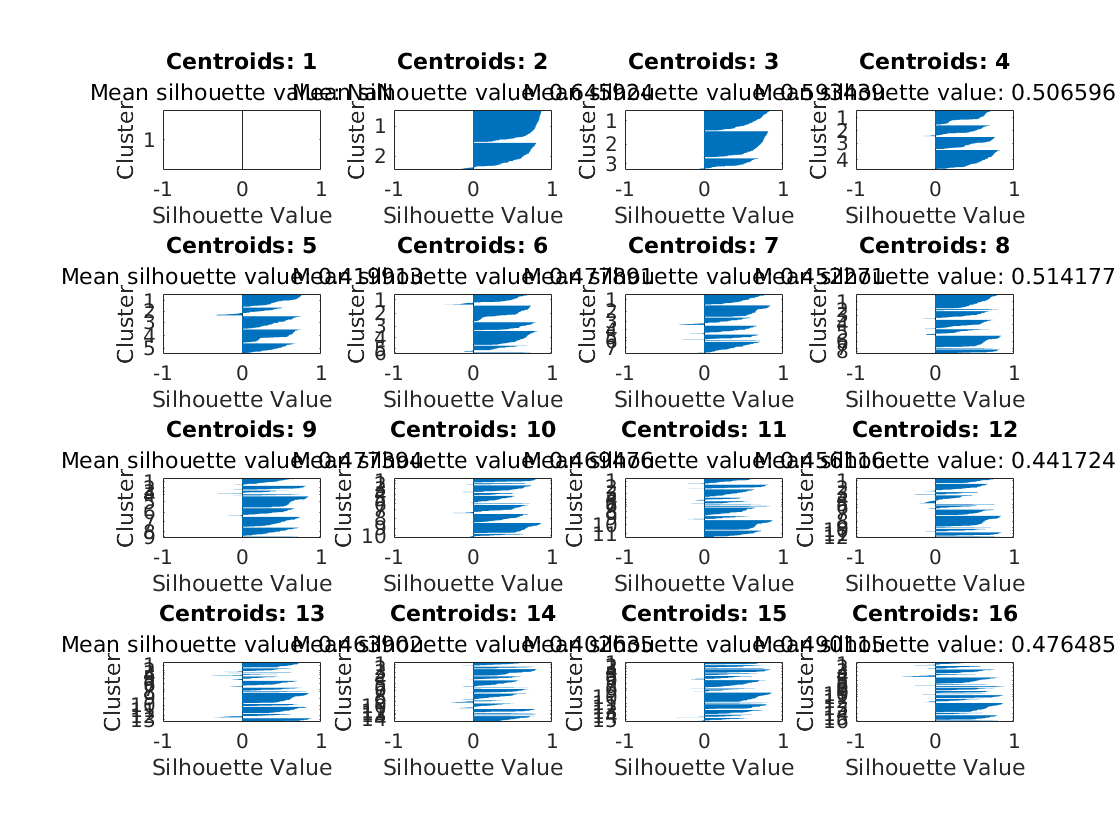

Sig2 = Sig2.GeRawTrainSet('Y','Y');

## Clustering and Raw unregularated templates generation

Clustering the features and further generating raw templates 

 [theSignalAnalysis] = KmeansGeRawSigTem(theSignalAnalysis,ClusterNum,Templot,Staplot)

Input--

**ClusterNum** Centroid numbers selected by the method in the above section, if leave it as blank select automatically by the matlab evalclusters functions, but it's suggested to choose according to the plot

**Templot **whether or not to show the plot with raw templates

**Staplot** whether or not to show the bar plot with each raw templates 

Output--

**Sig.NumTemplateRawUnRegu** Raw templates numbers

**Sig.TemplateRawUnRegu** a cell with each cell of corresponding raw templates data 

**Sig.TemplateRawUnReguCounts** two columns vector, first column count numbers for corresponding raw templates, second column for the count percentage of total spikes

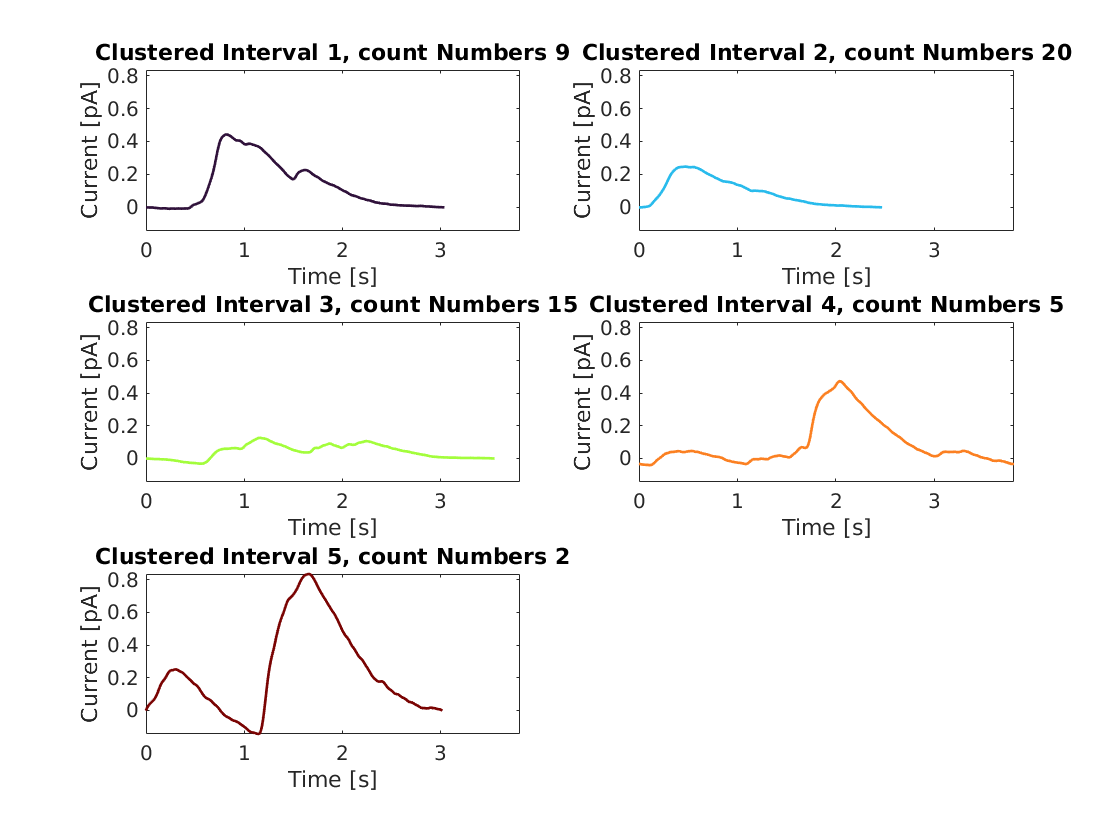

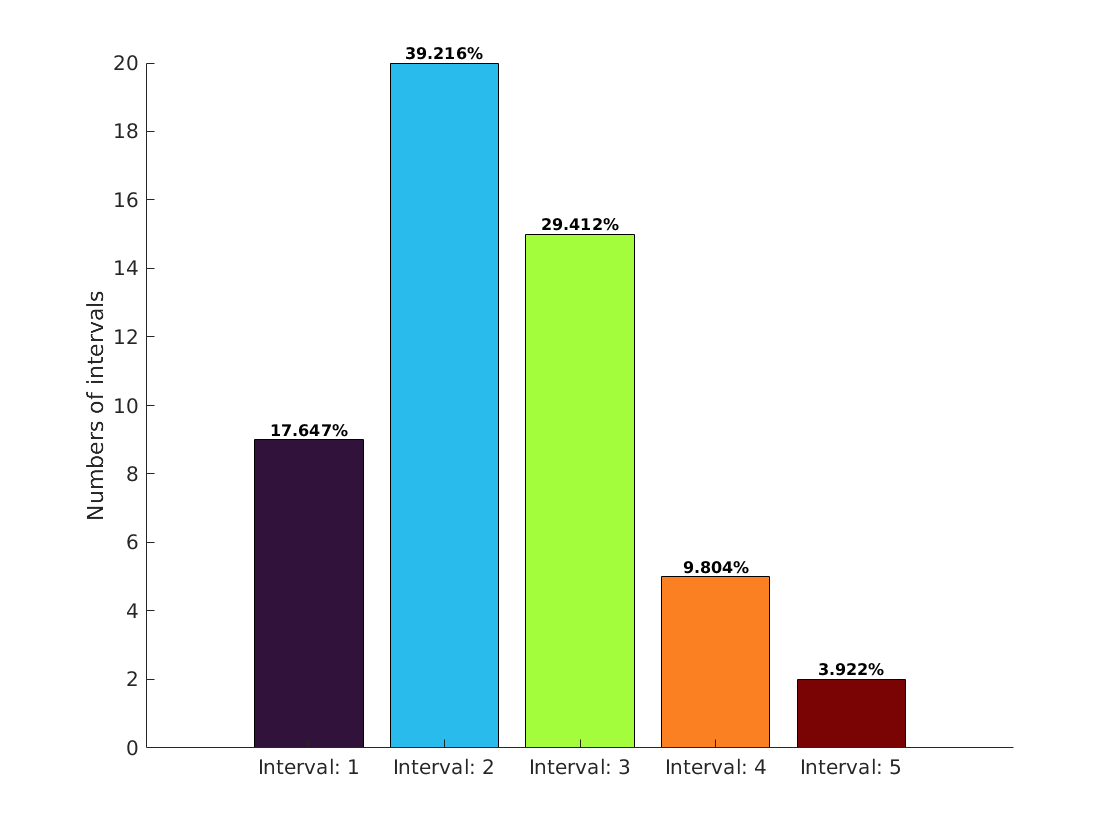

Sig1 = Sig1.KmeansGeRawSigTem(5,'Y',"Y");

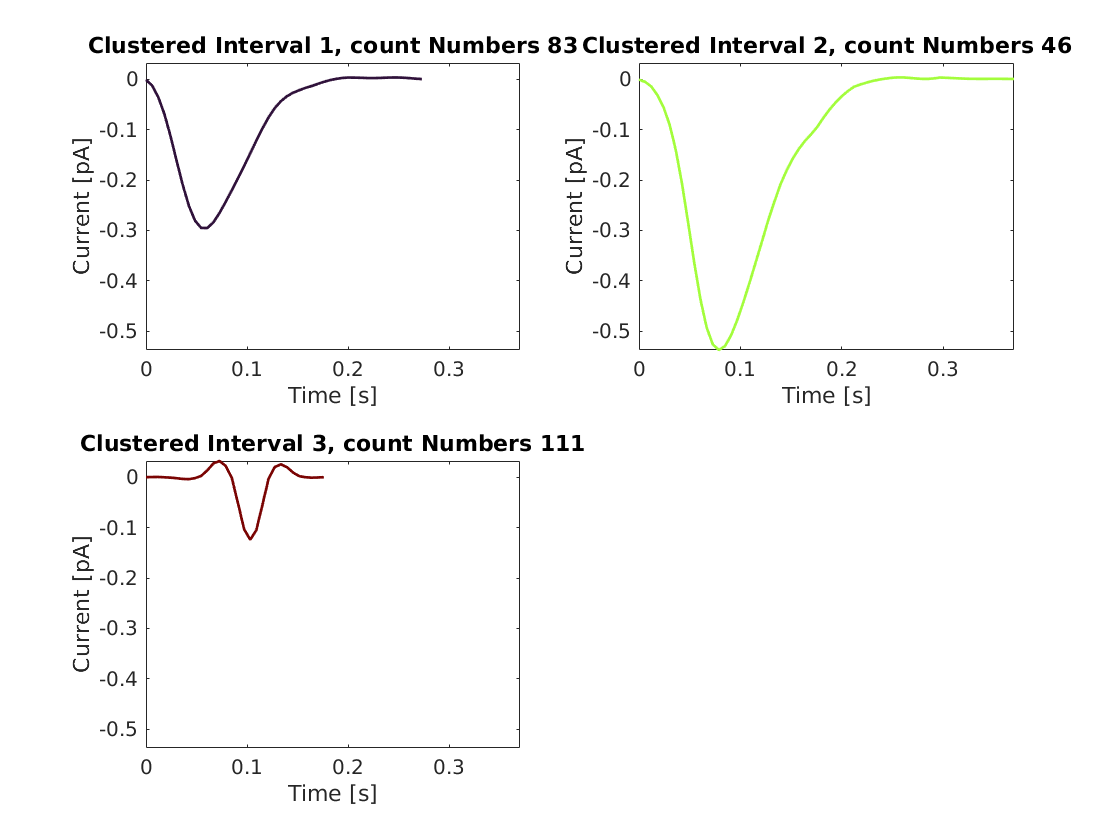

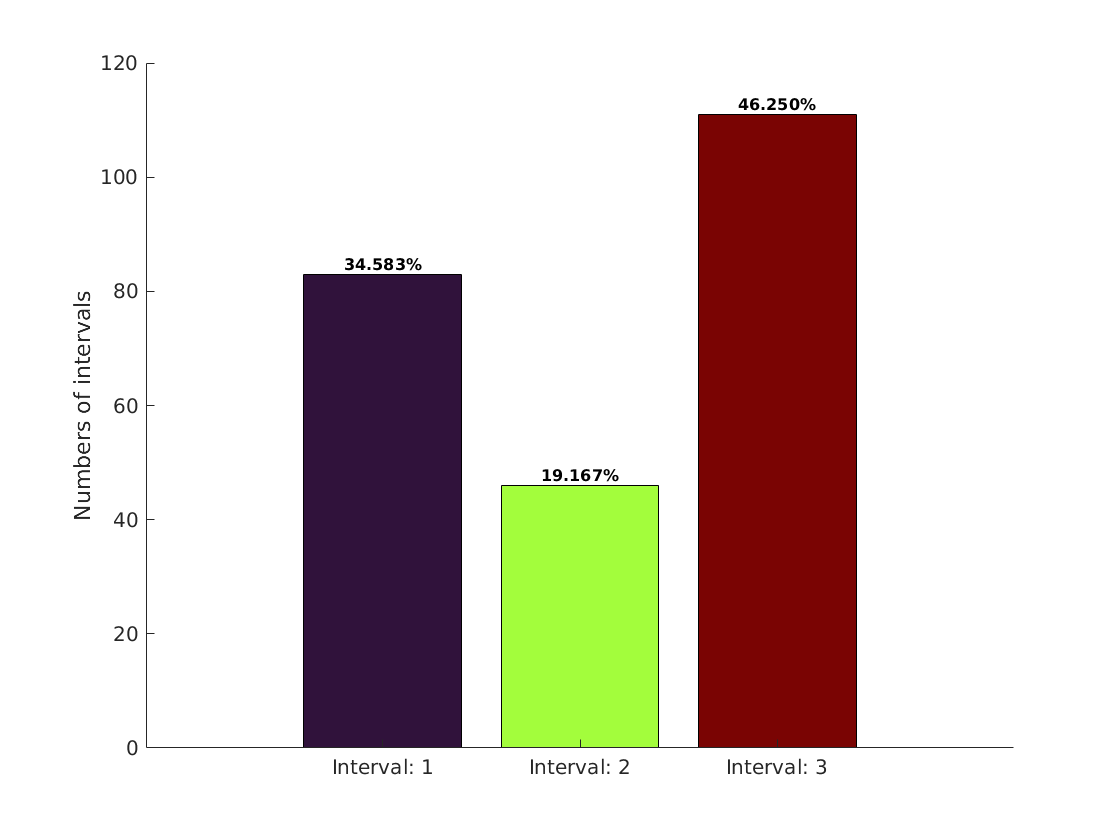

Sig2 = Sig2.KmeansGeRawSigTem(3,'Y',"Y");

## Regulated Templates

Removing the noisy templates and making raw templates fine

[theSignalAnalysis] = RawtemplatesReguFunc(theSignalAnalysis,ManSelectedNum,Plotstates)

Input--

**ManSelectedNum** a row vector of selected numbers of raw templates to perform the fine process.if it leaves as blank it will only take the raw templates more than 15%

**Plotstates** Whether or not to show the fine templates plot e.g. 'y'

Output--

**Sig.TemplatateRawRegu** A cell with fine templates 

**Sig.TemplatateRawReguNum **A vector with selected number

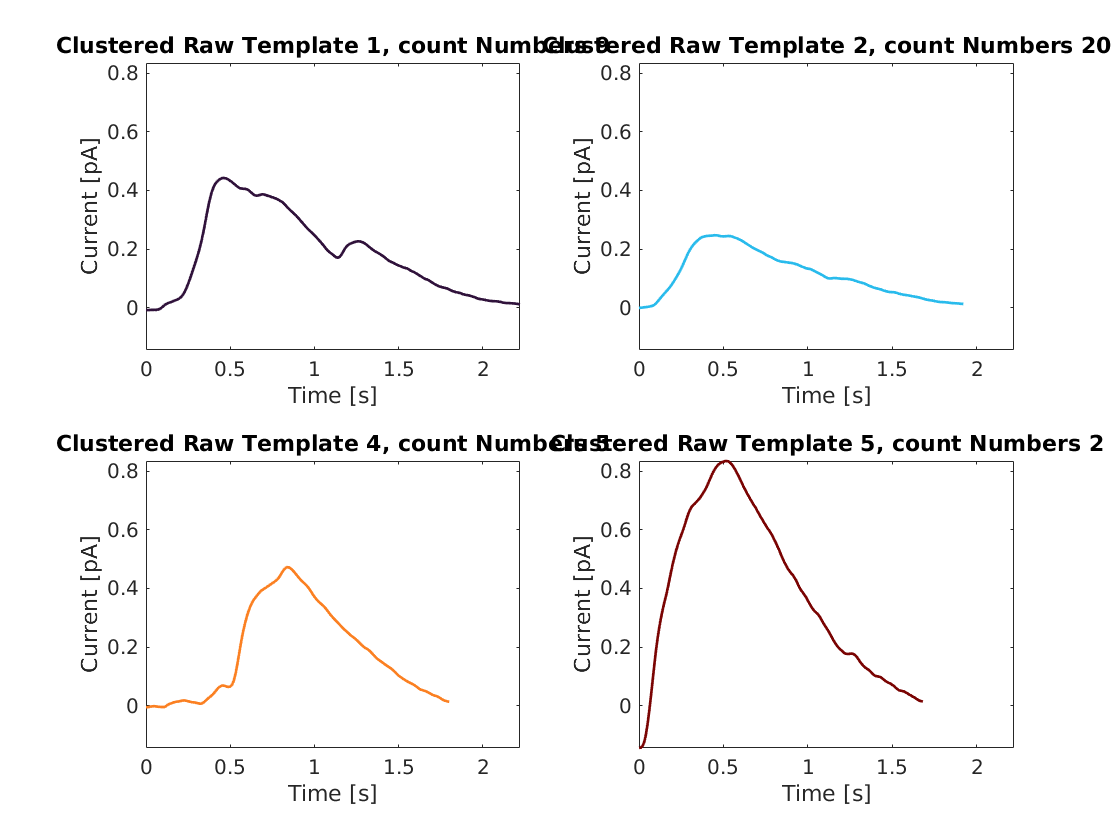

Sig1 = Sig1.RawtemplatesReguFunc([1,2,4,5],'Y');

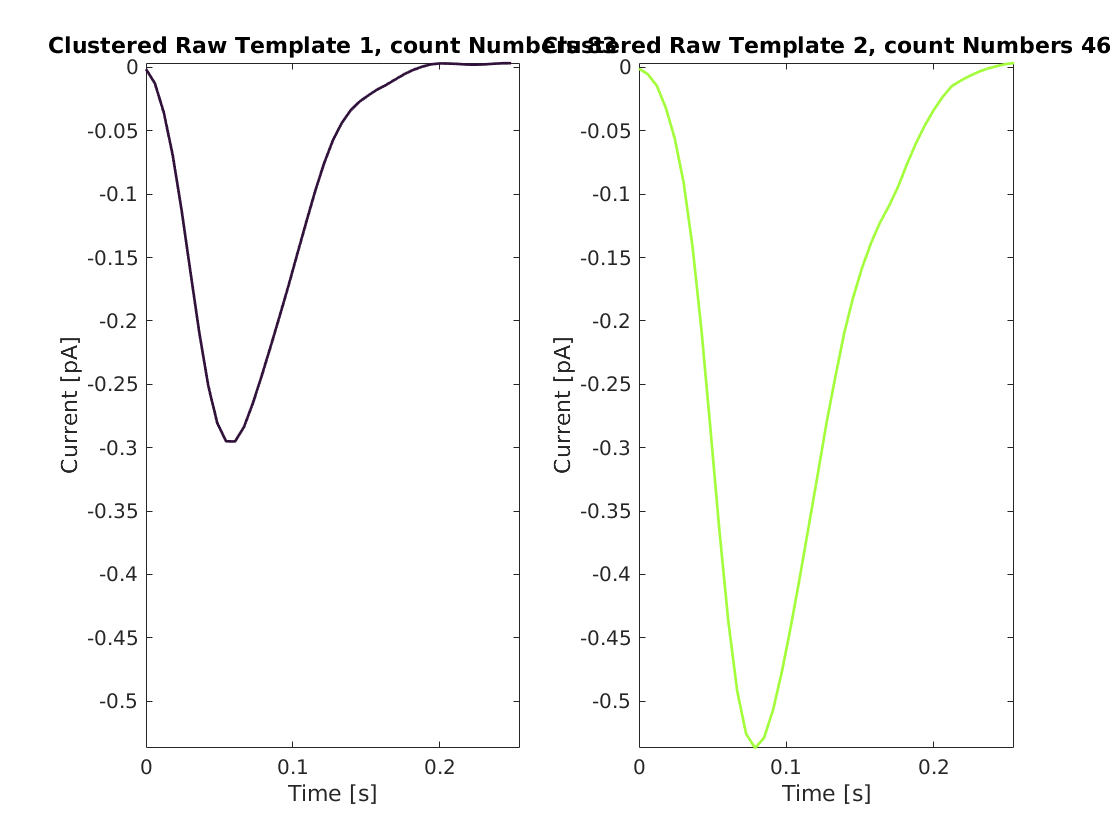

Sig2 = Sig2.RawtemplatesReguFunc([1,2],'Y');

## Template Matching

Perform the template matching with the fine templates

[theSignalAnalysis] = Templatematching(theSignalAnalysis,Plotstates)

--Input 

**Plotstates** Whether or not to show the similarity stem plots

-Output

**Sig.SimilarityLag** it's a cell. The first dimension is the template's number, the first column is the cosine similarity of each template, and the second is the corresponding interval for each similarity point in time. The left point defines the interval plus the template length as the right point.

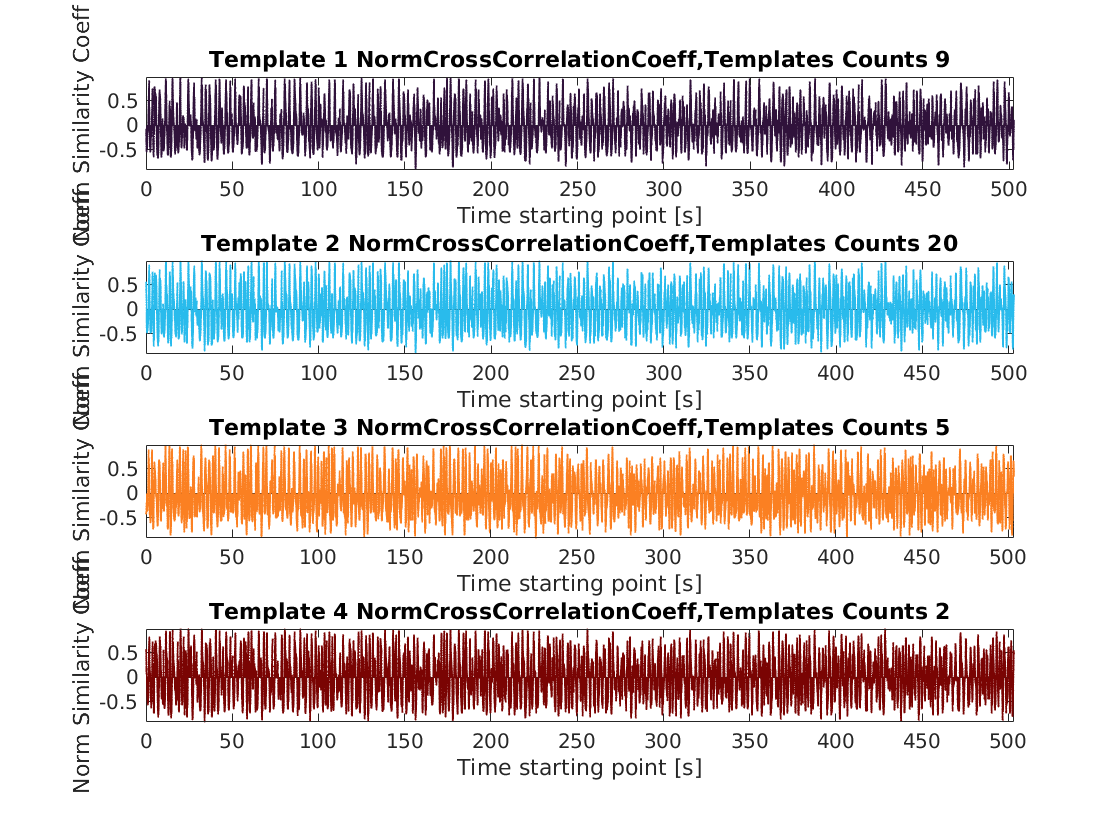

Sig1 = Sig1.Templatematching('Y');

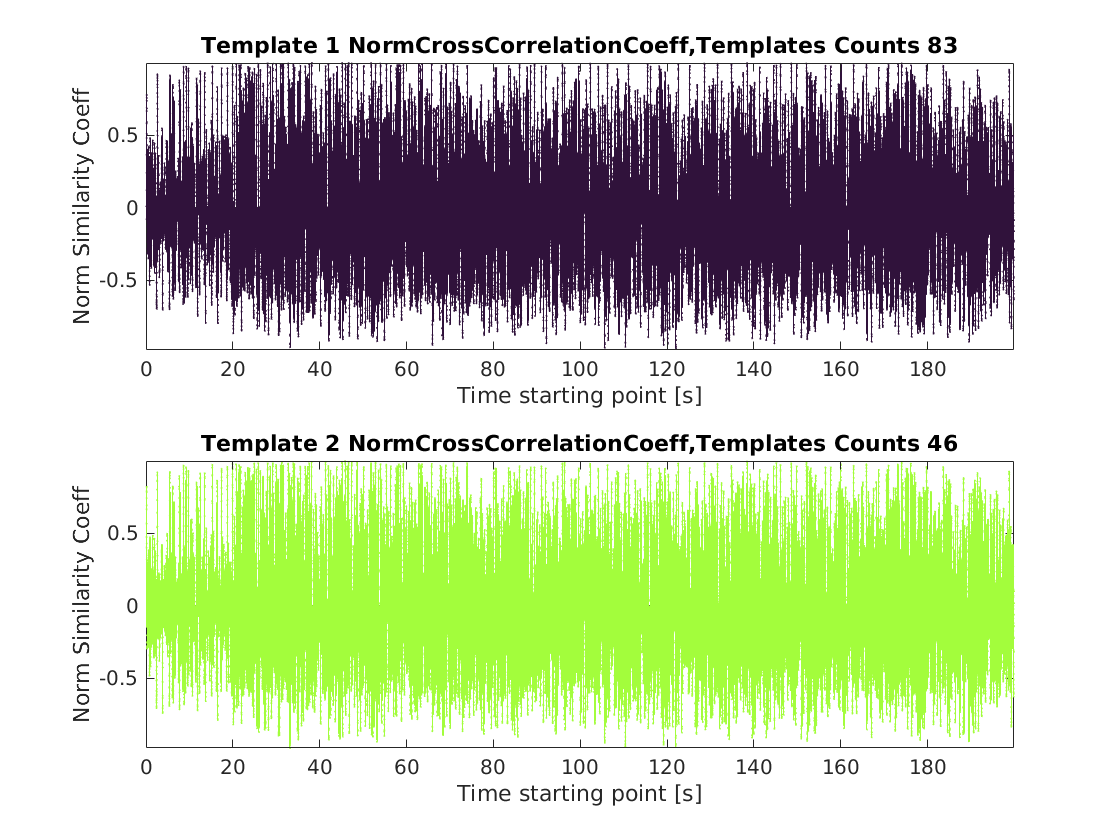

Sig2 = Sig2.Templatematching('Y');

## Template filtered the peaks AuNP NIE Sig1

Set the similarity threshold and numerical filter to obtain the desired span for each peak and merge them 

[theSignalAnalysis] = TemplatematchingFiltering(theSignalAnalysis,SimilarityLevel,StdFiltercoeff,HeightWidthratioCoeff,EachTemplateMatchCurve,TotalTemplateMatchCurev)

--Input 

**SimilarityLevel** Similarity threshold by default is set as 0.9

**StdFiltercoeff**, computed the correlated template's standard deviation(Temstd) and compared the matched span's standard deviation with StdFiltercoeff * Temstd. If it is smaller, then filter out the span. Mainly filter extreme short spikes. by default set as 0.35

**HeightWidthratioCoeff**, computed the ratio of the template's height and width ratio (TemRatio) and compared the matched spa's height-width ratio n with HeightWidthratioCoeff * TemRatio. If it is smaller, then filter out the span. Mainly filter extremely uneven spikes. by default as 0.35

**EachTemplateMatchCurve** Whether or not to show the span matched by each template, color same as the generated templates.

**TotalTemplateMatchCurve **Whether or not to show all merged spans of templates on the curve.

--Output

**Sig.TemplatateMatchedInte** A three-column matrix matched interval, first column left point, second column right point, third column peak point, they are all in indices of the sig.test_signal.

**Sig.AMInteSig **The data in each interval, the shorter span, get fed with zero to reach the same length.

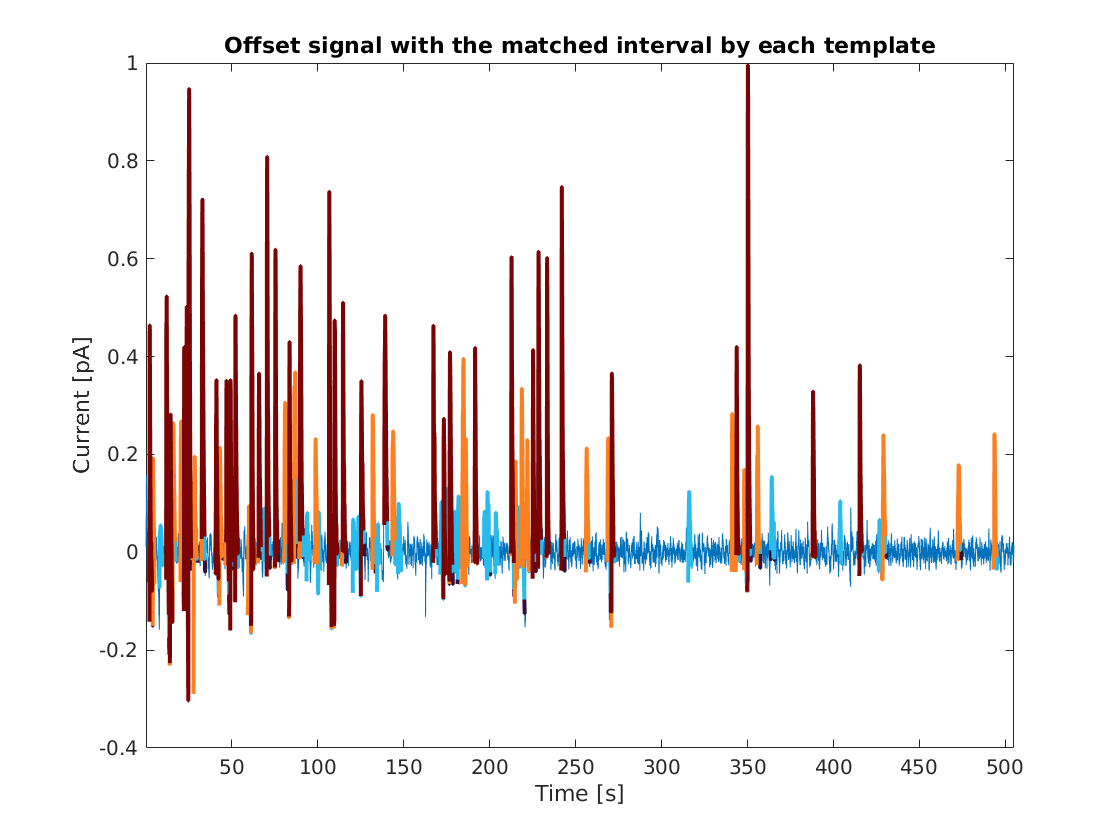

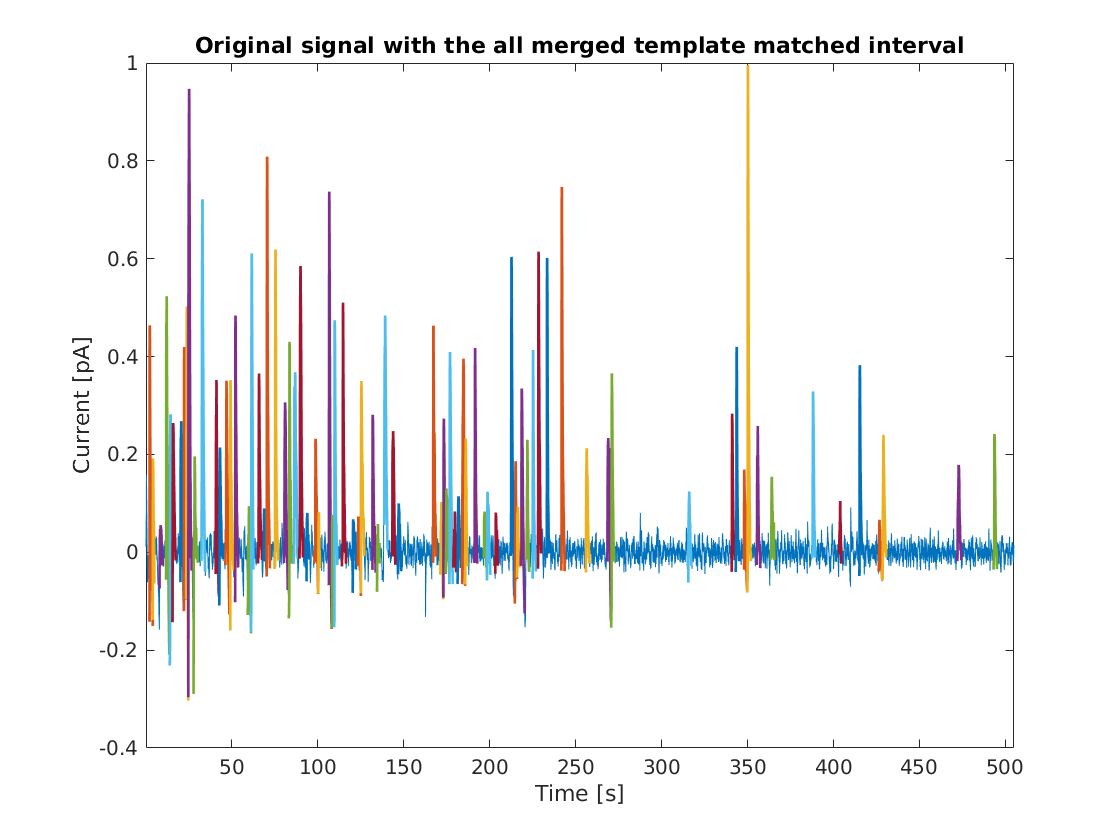

Sim = 0.9;
StdCoeff = 0.35;
HeightWidth = 0.35;
Sig1 = Sig1.TemplatematchingFiltering(Sim,StdCoeff,HeightWidth,'Y','Y');

## Template filtered the peaks Catalase NIE Sig2

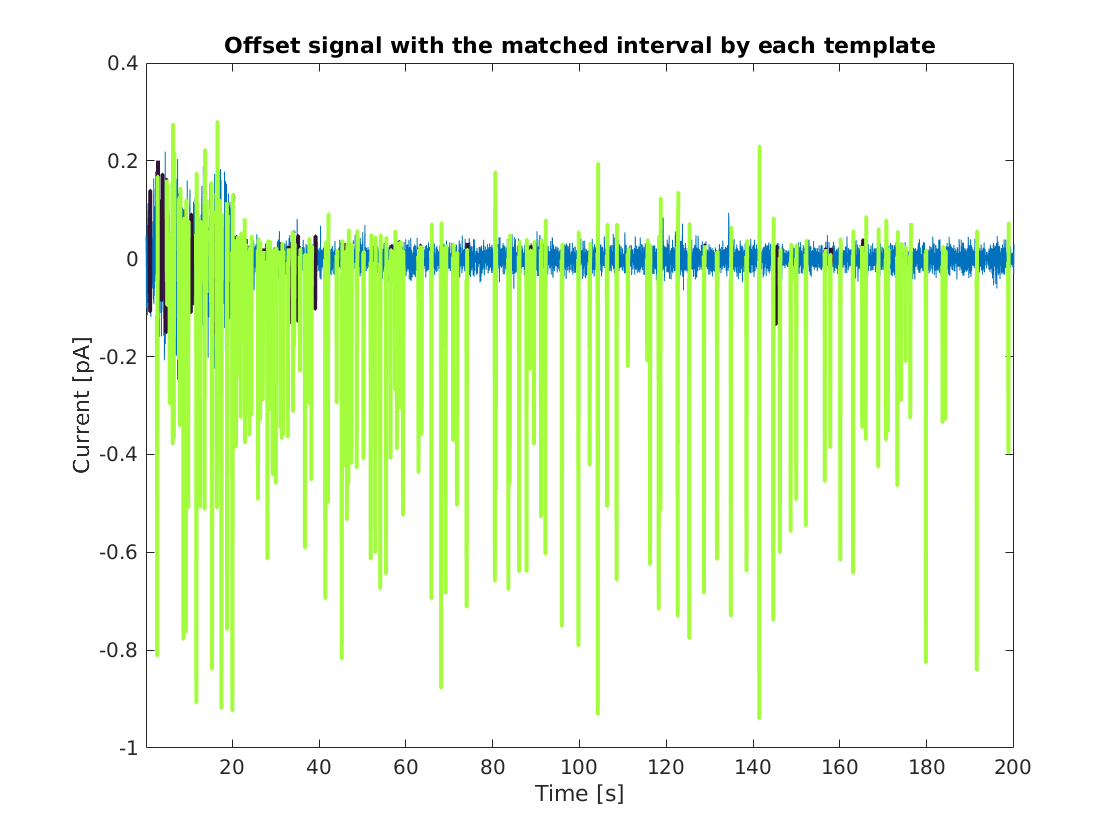

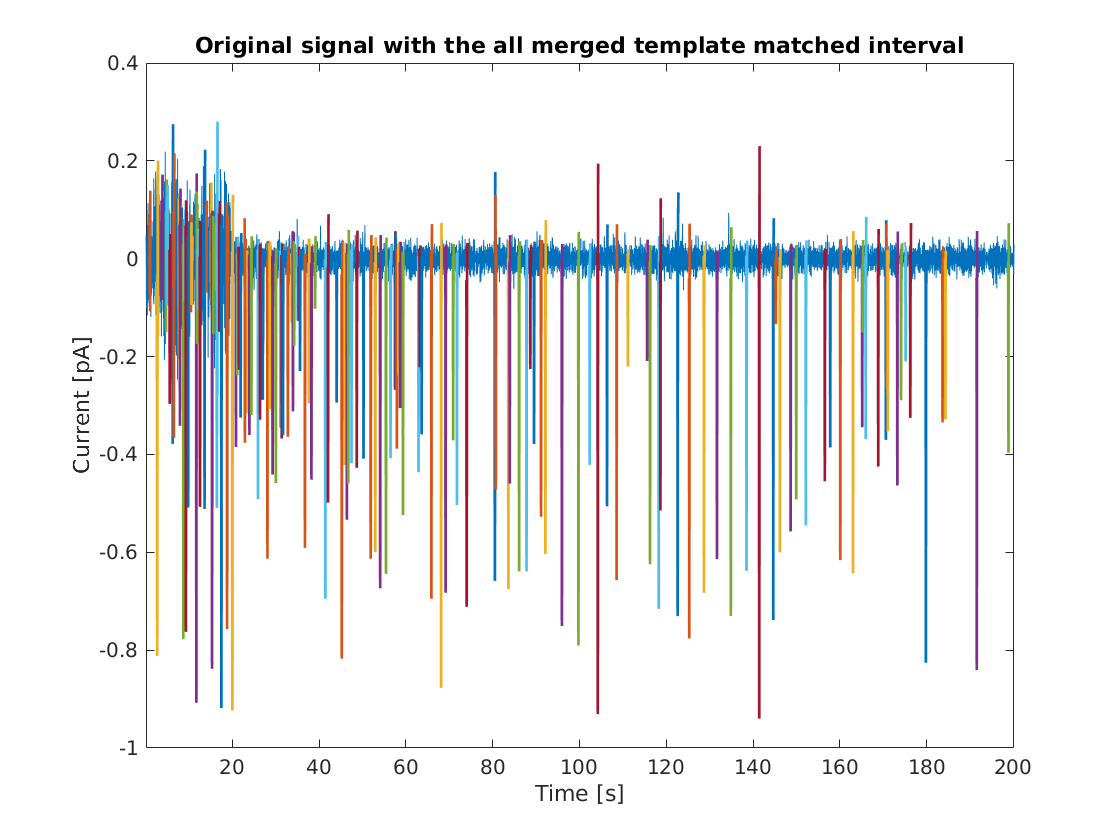

Sim = 0.9;
StdCoeff = 0.35;
HeightWidth = 0.35;
Sig2 = Sig2.TemplatematchingFiltering(Sim,StdCoeff,HeightWidth,'Y','Y');

## Information extraction and select centroid numbers for new templates

Extraction of each interval's physical meaning information and show the plot for centroid number selection

[theSignalAnalysis] = GeAMTrainSet(theSignalAnalysis,HeightFilter,NumPlot,SilPlot)

Input--

**HeightFilter **Whether or not to use the height threshold refilter, the matched span works for the deficient noise device by default is no

**NumPlot **Whether or not to show elbow method to select centroids numbers

**SilPlot** Whether or not to show silhouette score plot to select the centroid numbers 

Output--

**Sig.AMTrainingSet** is a table containing extracted information; each column contains the corresponding span's information.

**Sig.AMTrainingSetNorm** Z-score normalized Sig.AMTrainingSet

**Sig.AMTemPSigma** Each column's standard deviation value

**Sig.AMTemPMu** Each column's mean value

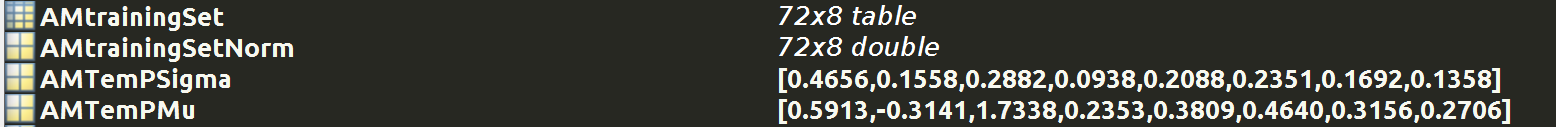

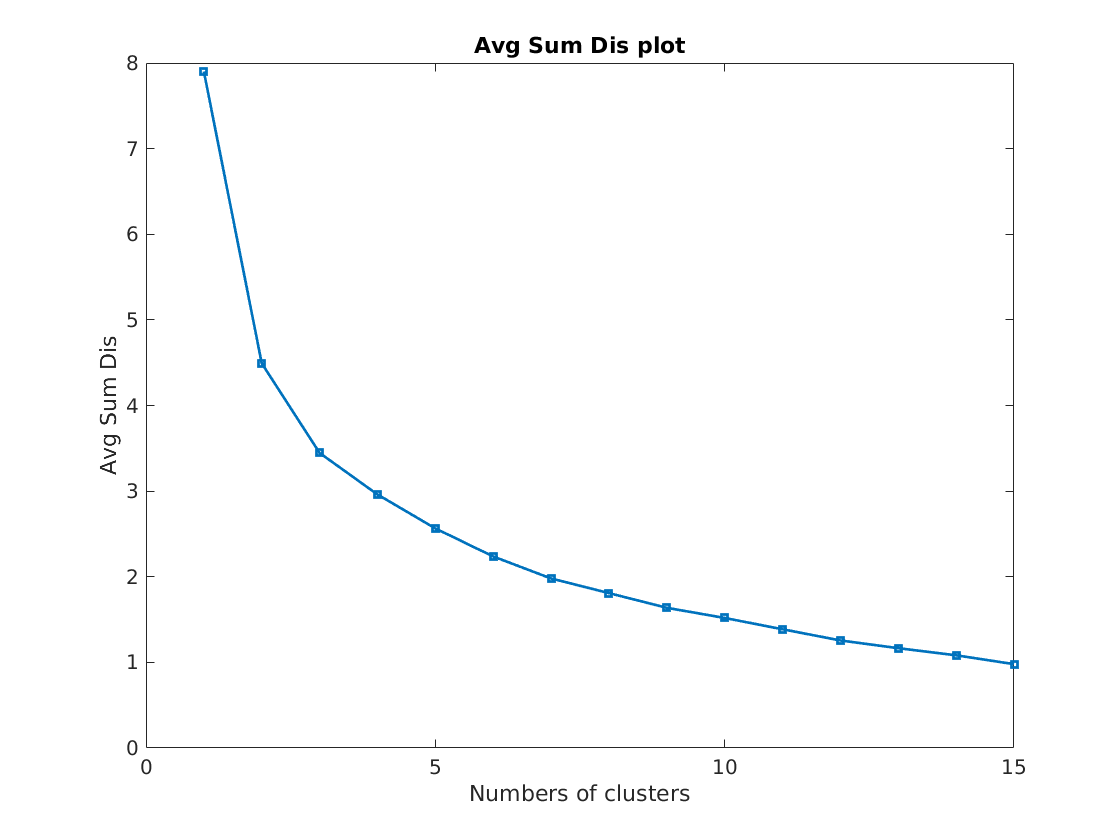

Sig1 = Sig1.GeAMTrainSet('N','Y',"N");

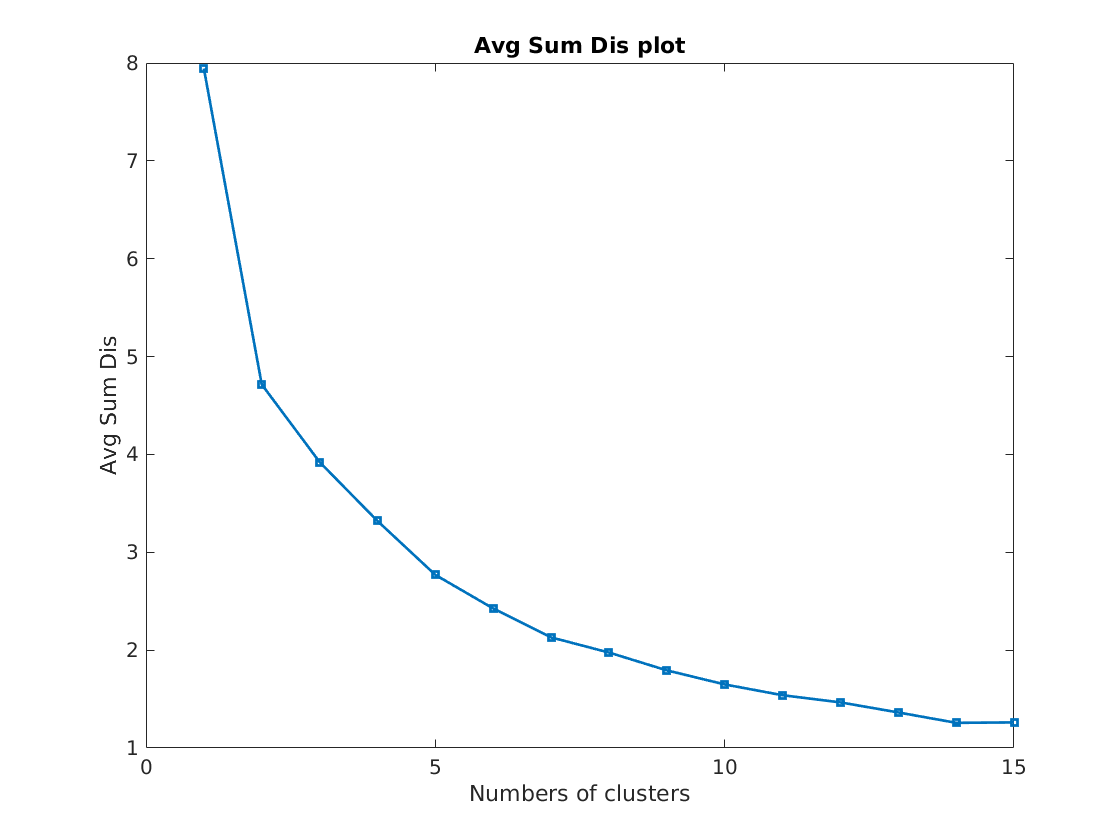

Sig2 = Sig2.GeAMTrainSet('Y','Y',"N");

## ReClustering and generate the templates

Reclutsering the peak spans and generate the new templates

[theSignalAnalysis] = KmeansGeAMSigTem(theSignalAnalysis,ClusterNum,MarkPlot,TotalPlot)

Input--

**ClusterNum** selected cluster number, if leave as blank same as the regulated templates's number

**MarkPlot** Whether or not marked the found interval on the original plot 

**TotalPlot** Whether or not show a summary plot with extarcted information, the histograms consider hthe peak amounts, area, height and duration

Output -- 

**Sig.AMTemCen **Centroid of the clusters are converted back to the un-normalized data. each column is same as the Sig.AMTrainingSet

**Sig.AMTemplates **A cell contain each templates

**Sig.AMTemidx** The index of each matched span to the assigned cluster 

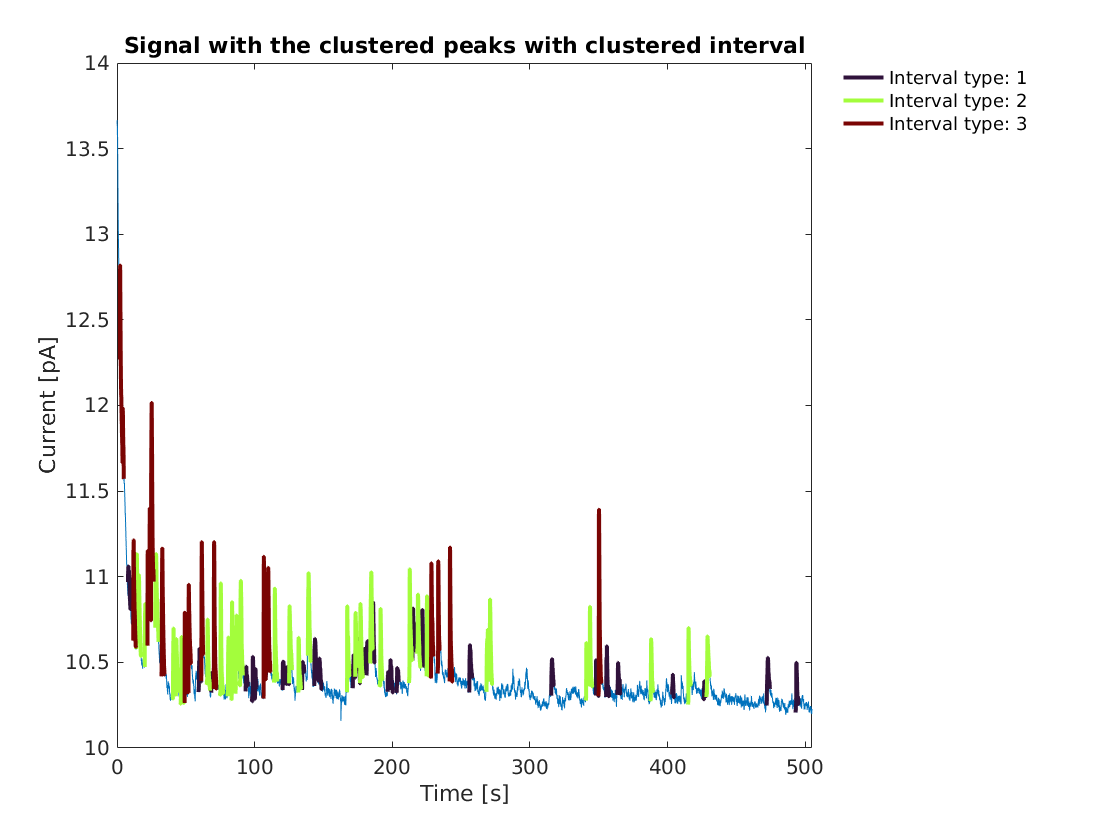

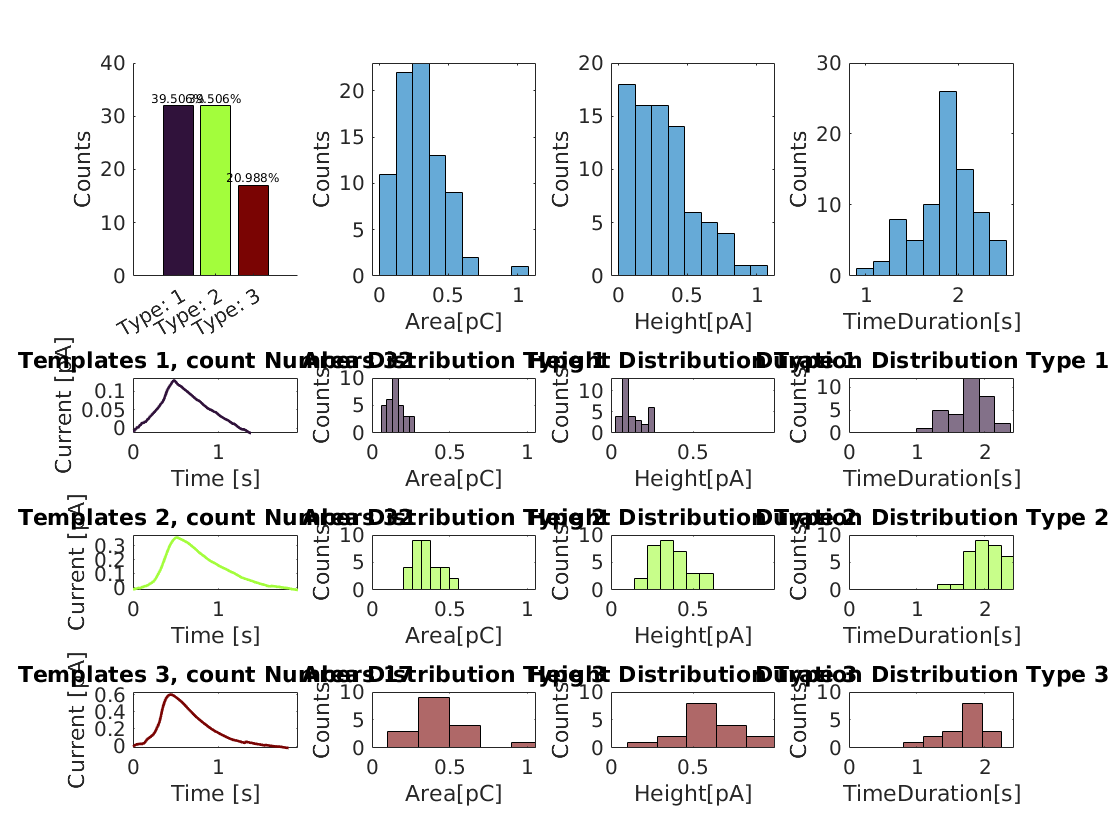

Sig1 = Sig1.KmeansGeAMSigTem(3,"Y","Y");

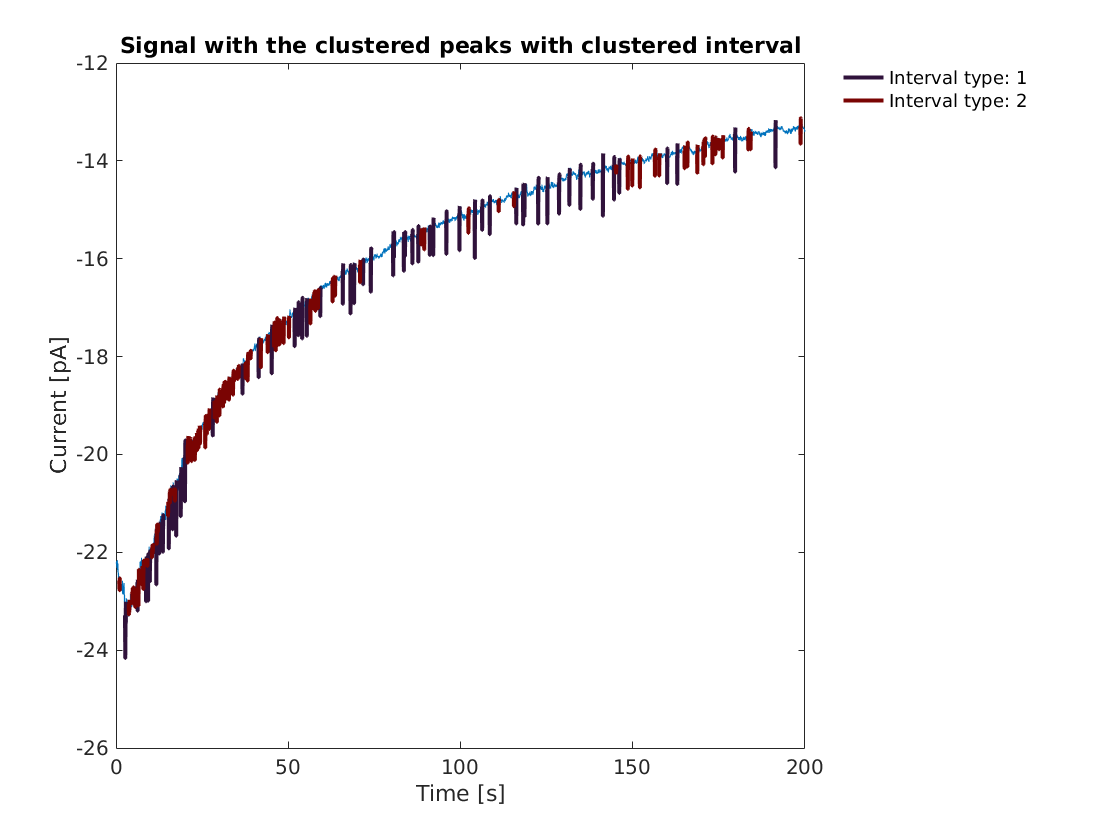

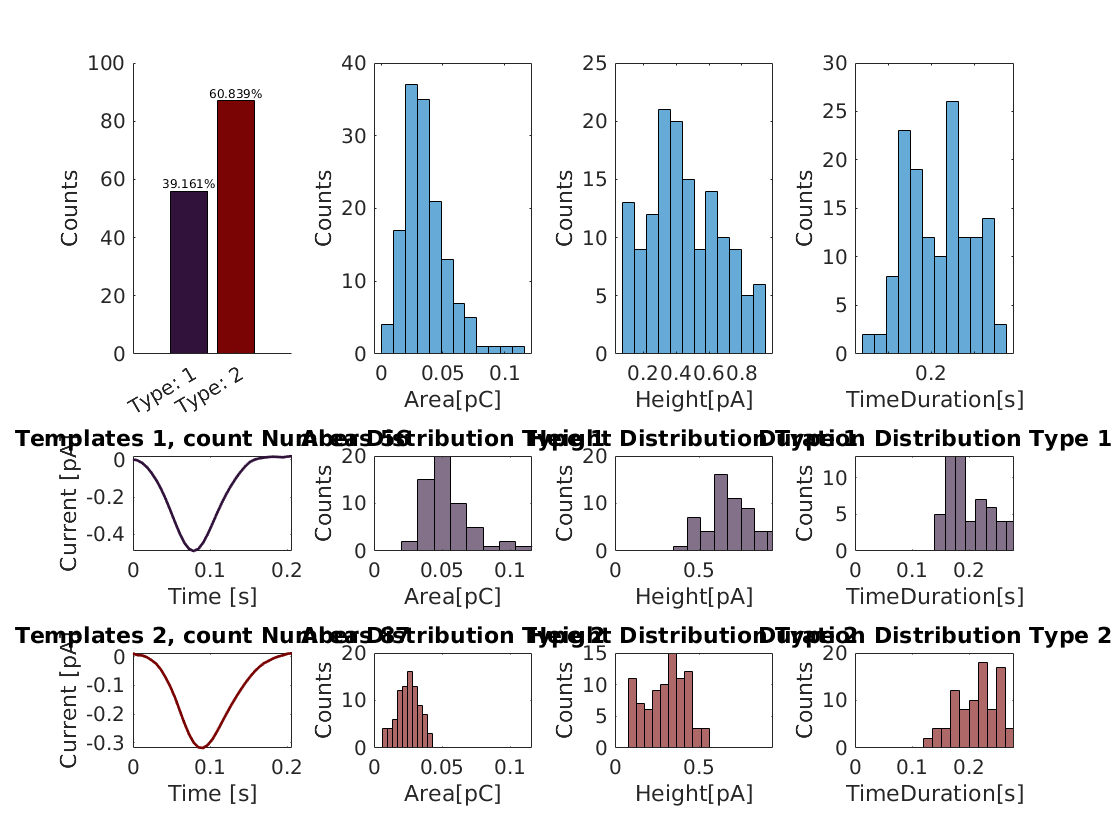

Sig2 = Sig2.KmeansGeAMSigTem(2,"Y","Y");

## Rematching Effect

It will replace the regulated raw templates by the new templates, and perform the rematching by the new templates.

[theSignalAnalysis] = Rematching(theSignalAnalysis,TimesRematching,MarkPlot,TotalPlot)

--Input

**TimesRematching** how many times the rematching is performed, by default as 1

**MarkPlot** Whether or not marked the found interval on the original plot 

**TotalPlot** Whether or not show a summary plot with extarcted information, the histograms consider hthe peak amounts, area, height and duration

-- Output 

Changes on the output of KmeansGeAMSigTem

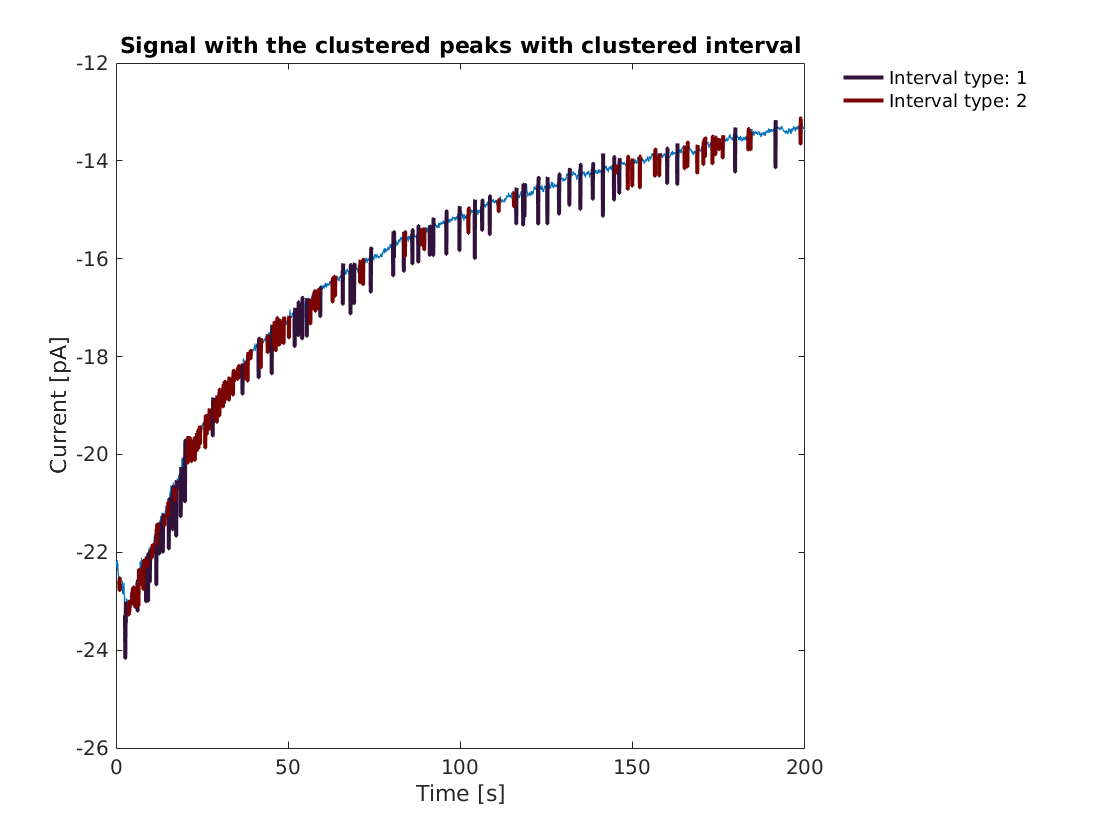

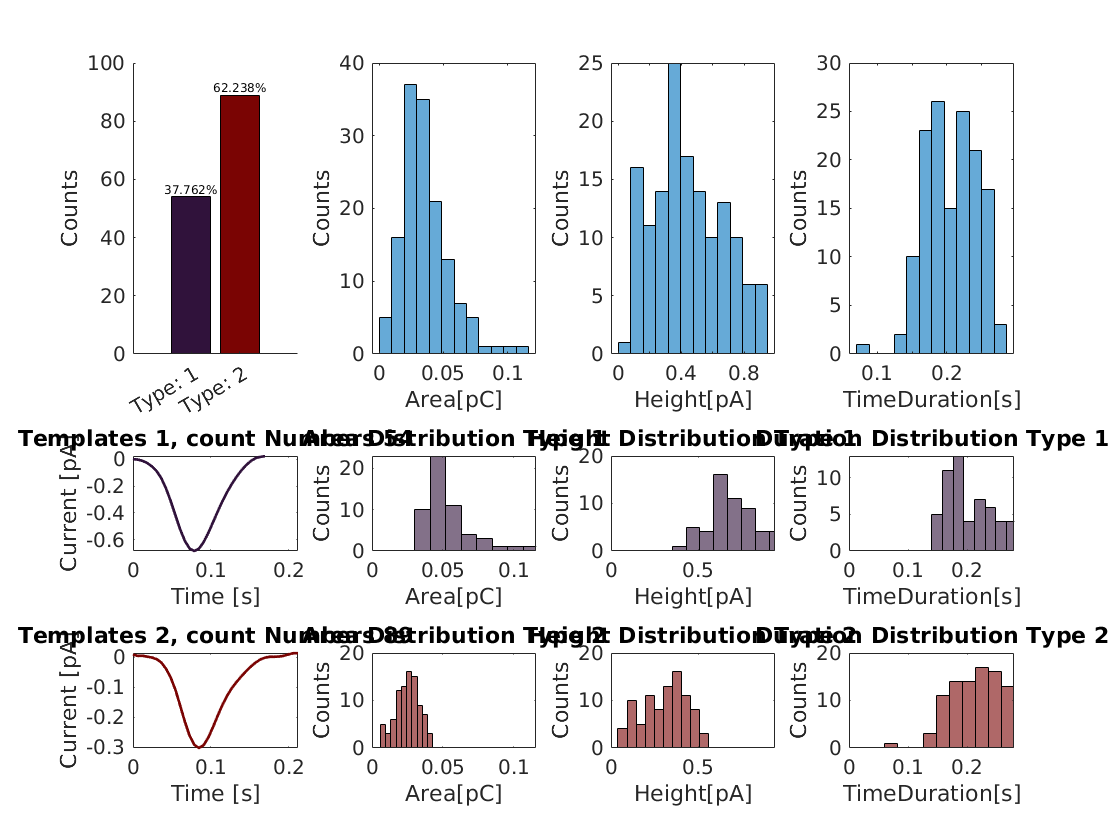

Sig3 = Sig2.KmeansGeAMSigTem(2,"N","N");
Sig3 = Sig3.Rematching(2,"Y","Y");